%% Question 3a)
input_vector = rand(8,1);
scalar_threshold = 0.5;

%testing
decision = neuron(input_vector, scalar_threshold);

disp('Input vector:');

Input vector:


disp(input_vector);

    0.9503
    0.4980
    0.8175
    0.7357
    0.1582
    0.7916
    0.0137
    0.7235



disp('Does the neuron fire? (1 = yes, 0 = no)');

Does the neuron fire? (1 = yes, 0 = no)


disp(decision);

     1




%% Question 3b)
scalar_threshold = 0.5;
T = 60;

%3c)
time_vector = 1:T;
plot_vector = zeros(1, T);


for xx = time_vector
    plot_vector(xx) = neuronOverTime(scalar_threshold, T);
end 

Firing activity over time:
     0

Firing activity over time:
     1

Firing activity over time:
     1

Firing activity over time:
     1

Firing activity over time:
     0

Firing activity over time:
     1

Firing activity over time:
     0

Firing activity over time:
     0

Firing activity over time:
     0

Firing activity over time:
     0

Firing activity over time:
     0

Firing activity over time:
     0

Firing activity over time:
     0

Firing activity over time:
     1

Firing activity over time:
     1

Firing activity over time:
     0

Firing activity over time:
     0

Firing activity over time:
     1

Firing activity over time:
     0

Firing activity over time:
     1

Firing activity over time:
     0

Firing activity over time:
     0

Firing activity over time:
     0

Firing activity over time:
     1

Firing activity over time:
     0

Firing activity over time:
     0

Firing activity over time:
     0

Firing activity over time:
     1

Firing activity over

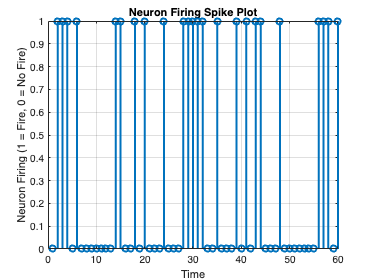


figure;
stem(time_vector, plot_vector, 'LineWidth', 2);hold on; 
xlabel('Time');
ylabel('Neuron Firing (1 = Fire, 0 = No Fire)');
title('Neuron Firing Spike Plot');
grid on;

%3a)

function decision = neuron(input_vector, scalar_threshold)
dendrite1 = mean(input_vector);
dendrite2 = mean(input_vector(5:8));
dendrite3 = input_vector(8);

%check firing or not
check_firing = 0;
if dendrite1 > scalar_threshold
    check_firing = check_firing +1;
end 

if dendrite2 > scalar_threshold
    check_firing = check_firing +1;
end 

if dendrite3 > scalar_threshold
    check_firing = check_firing +1;
end 

if check_firing >=2
    decision = 1;
else 
    decision = 0;
end 

end 

%3b)
function decision_over_time = neuronOverTime(scalar_threshold, T)
input_vector = rand(1, T);
padded_input = [zeros(1, 7), input_vector];

for t = 1:T
    real_inputs = padded_input(t:t+7)';
    decision_over_time = neuron(real_inputs, scalar_threshold);
end 

    disp('Firing activity over time:');
    disp(decision_over_time);

end 